# 散点拟合成圆的经典方法

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

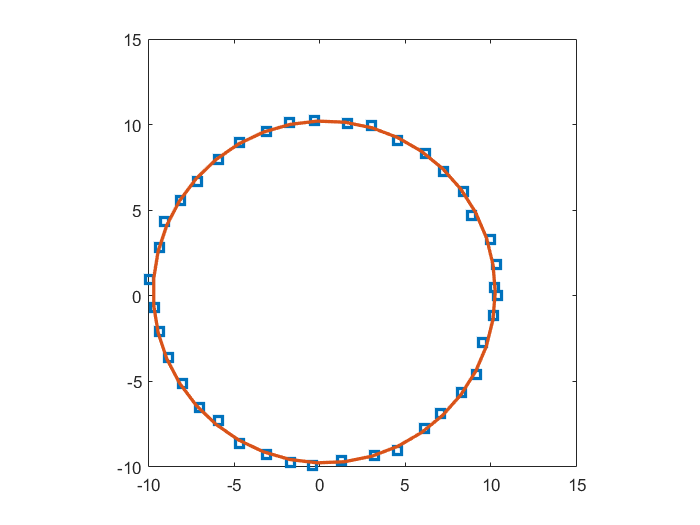

clear;clc;
M = 40;
theta = linspace(0, 2 * pi, M)';
r = 10;
ratio = 0.5;
x = r * cos(theta) + ratio * rand(M, 1);
y = r * sin(theta) + ratio * rand(M, 1);
xy = [x, y];
par = CircleFitByTaubin(xy);
x0 = par(1);
y0 = par(2);
r0 = par(3);
xfit = x0 + r0 * cos(theta);
yfit = y0 + r0 * sin(theta);
plot(x, y, 's', xfit ,yfit, 'linewidth', 2);
axis square

# 拟合圆方程

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

- Input:  XY(n,2); x = XY(:, 1); y = XY(:, 2)

- Output: Par = [a, b, R]; center (a,b) and radius R

- 调用示例

function Par = CircleFitByTaubin(XY)
% number of data points
n = size(XY,1);     
% the centroid of the data set
centroid = mean(XY);   
% computing moments (note: all moments will be normed, i.e. divided by n)
Mxx = 0; Myy = 0; Mxy = 0; Mxz = 0; Myz = 0; Mzz = 0;
for i=1:n
    Xi = XY(i,1) - centroid(1);  %  centering data
    Yi = XY(i,2) - centroid(2);  %  centering data
    Zi = Xi*Xi + Yi*Yi;
    Mxy = Mxy + Xi*Yi;
    Mxx = Mxx + Xi*Xi;
    Myy = Myy + Yi*Yi;
    Mxz = Mxz + Xi*Zi;
    Myz = Myz + Yi*Zi;
    Mzz = Mzz + Zi*Zi;
end
Mxx = Mxx/n;
Myy = Myy/n;
Mxy = Mxy/n;
Mxz = Mxz/n;
Myz = Myz/n;
Mzz = Mzz/n;
%    computing the coefficients of the characteristic polynomial
Mz = Mxx + Myy;
Cov_xy = Mxx*Myy - Mxy*Mxy;
A3 = 4*Mz;
A2 = -3*Mz*Mz - Mzz;
A1 = Mzz*Mz + 4*Cov_xy*Mz - Mxz*Mxz - Myz*Myz - Mz*Mz*Mz;
A0 = Mxz*Mxz*Myy + Myz*Myz*Mxx - Mzz*Cov_xy - 2*Mxz*Myz*Mxy + Mz*Mz*Cov_xy;
A22 = A2 + A2;
A33 = A3 + A3 + A3;
xnew = 0;
ynew = 1e+20;
epsilon = 1e-12;
IterMax = 20;
% Newton's method starting at x=0
for iter=1:IterMax
    yold = ynew;
    ynew = A0 + xnew*(A1 + xnew*(A2 + xnew*A3));
    if abs(ynew) > abs(yold)
        disp('Newton-Taubin goes wrong direction: |ynew| > |yold|');
        xnew = 0;
        break;
    end
    Dy = A1 + xnew*(A22 + xnew*A33);
    xold = xnew;
    xnew = xold - ynew/Dy;
    if (abs((xnew-xold)/xnew) < epsilon)
        break;
    end
    if (iter >= IterMax)
        disp('Newton-Taubin will not converge');
        xnew = 0;
    end
    if (xnew<0.)
        fprintf(1,'Newton-Taubin negative root:  x=%f\n',xnew);
        xnew = 0;
    end
end
%  computing the circle parameters
DET = xnew*xnew - xnew*Mz + Cov_xy;
Center = [Mxz*(Myy-xnew)-Myz*Mxy , Myz*(Mxx-xnew)-Mxz*Mxy]/DET/2;
Par = [Center+centroid , sqrt(Center*Center'+Mz)];
end    %    CircleFitByTaubin